# Project 2: MAE 5510

In this project, you will be

- Finding a self-consistent set of operating conditions for a particular single spool turbojet engine under take-off conditions.

- Investigating the performance of a range of compressor designs.

## Assumptions to be made in this Project

- Inlet is ideal

- Nozzle is ideal

- Combustor is ideal, i.e. $P_{t3} = P_{t4}$, $\eta_b = 1$.

- The quantity of heat transferred in the combustor is $\eta_b \dot{m_f } Q_f$.

- Fuel mas flow rate is negligible compared to air mass flow rate

- $\gamma=1.4$ and $MW=0.02896 $ kg/mol throughout the engine. $c_p$ shall be calculated using this information.

- There are no internal irreversibilities in the streamtube leading up to the inlet.

- Reference pressures and temperatures are $T_{\textrm{ref}} =288\ldotp 15$ K and $P_{\textrm{ref}} =101325$ Pa.

## Project Flow

The motive of this project is to familiarize students with matching procedure using turbomachinery maps. You will also conduct a parametric study of turbomachines and its impact on engine performance. Here is the flow of project:

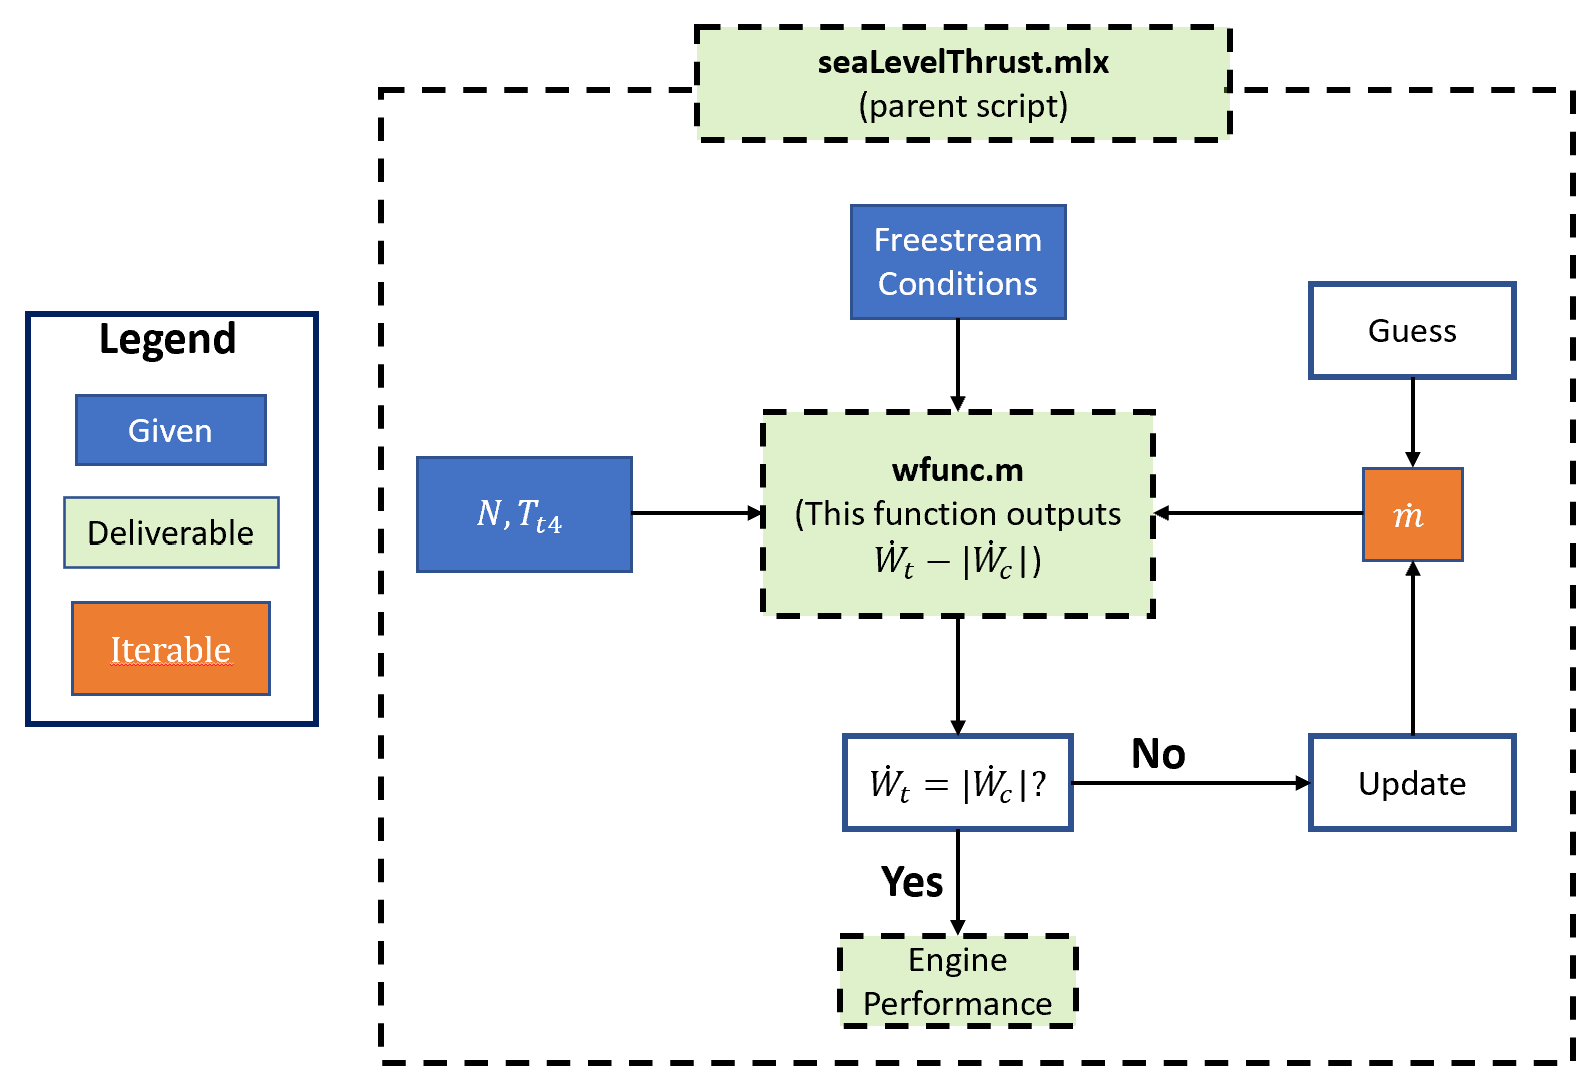

You are working on seaLevelThrust.mlx currently, and this live script will guide you through implementation of rest of the code.

## Background

The numbers used here are inspired by General Electric GE4 single-spool turbojet engine which was designed in late 1960s to power Boeing 2707 supersonic transport. The image of engineers assembling this engine is shown below:

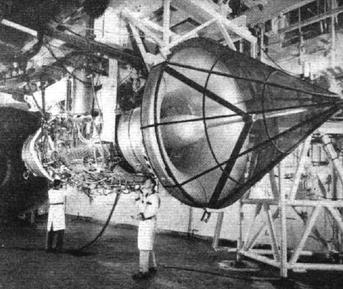

The engine had afterburning capabilities and produced thrust of 220 kN (50,000 lbf) without afterburner and 290 kN (65,000 lbf). Your results will be of the similar order but not exactly same as we do not have compressor and turbine maps generated through rig testing. The maps used here are generated using Blade Element Theory, which is an analytical approximation of compressor performance. This theory is briefly described in Sforza, section 7.8, and covered in detail in chapter 8.

**Lets get started!**

To use these values, we need to define thermodynamics quantities $\gamma$, MW, $R$, $c_p$, $T_{\textrm{ref}}$, and $P_{\textrm{ref}}$. Define these quantities in code below:

clear

gamma = 1.4;                                                                % Ratio of specific heat, typically 1.4 for diatomic gases and low temperature gases
Ru = 8.314;                                                                 % Universal gas constant (J/K/mol)
M_air = 28.96;                                                              % Molecular mass of air (g/mol)
R = Ru*1000/M_air;                                                          % Specific gas constant of air (J/Kg/K)
cp = gamma*R/(gamma - 1);                                                   % Specific heat at constant pressure for gamma = 1.4 (J/kg/K)
Tref = 288.15;                                                              % Reference Temperature (K)
Pref = 101325;

## Freestream Conditions

We first want to gauge the performance of our turboimachinery on sea level. Since we will be testing our turbomachinery mounted on a rig in a test stand (very similar to picture above), our freestream conditions are that of sea level such that $M_0 =0$, $T_0 =288\ldotp 15$ K, and $P_0 =101325$ Pa. Define $M_0$, $T_0$, $V_0$ and $P_0$ in the code below:

M0 = 0;
T0 = 288.15;
P0 = 101325;
V0 = M0*sqrt(gamma*R*T0);                                                      % Reference Pressure (Pa)

As thermodynamic analysis is very simple in terms of stagnation properies, from this point forward, we will try to solve as much as we can using stagnation properties. Using the variables defined till now, define stagnation properties $T_{\textrm{t0}}$, $P_{\textrm{t0}}$.

Tt0 = T0*(1 + (gamma - 1)/2*M0^2);
Pt0 = P0*(Tt0/T0)^(gamma/(gamma - 1));

## Inlet

Now that you know the stagnation properties at state 0, use these values to determine $T_{\textrm{t2}}$, $P_{\textrm{t2}}$ using appropriate assumptions.

Pt2 = Pt0;                                                                  % Section 6.5.2 in Fig 6.8 shows pressure recovery of almost unity for high BPR subsonic turbofans
Tt2 = Tt0;                                                                  % No heat addtion

## Turbomachinery Maps

Finally! The most exiciting part! Let's get started.

The take-off demands maximum power, and it is known that the engine material limits maximum turbine inlet temperatures at $T_{\textrm{t4}} =1400$ K. Based on flow experiments it is known that these temperatures result in 5800 RPM at sea-level conditions. The turbojet has Inlet Guide Vanes (IGV), 9-stage compressor driven by 2-stage turbine, as shown in the figure below:

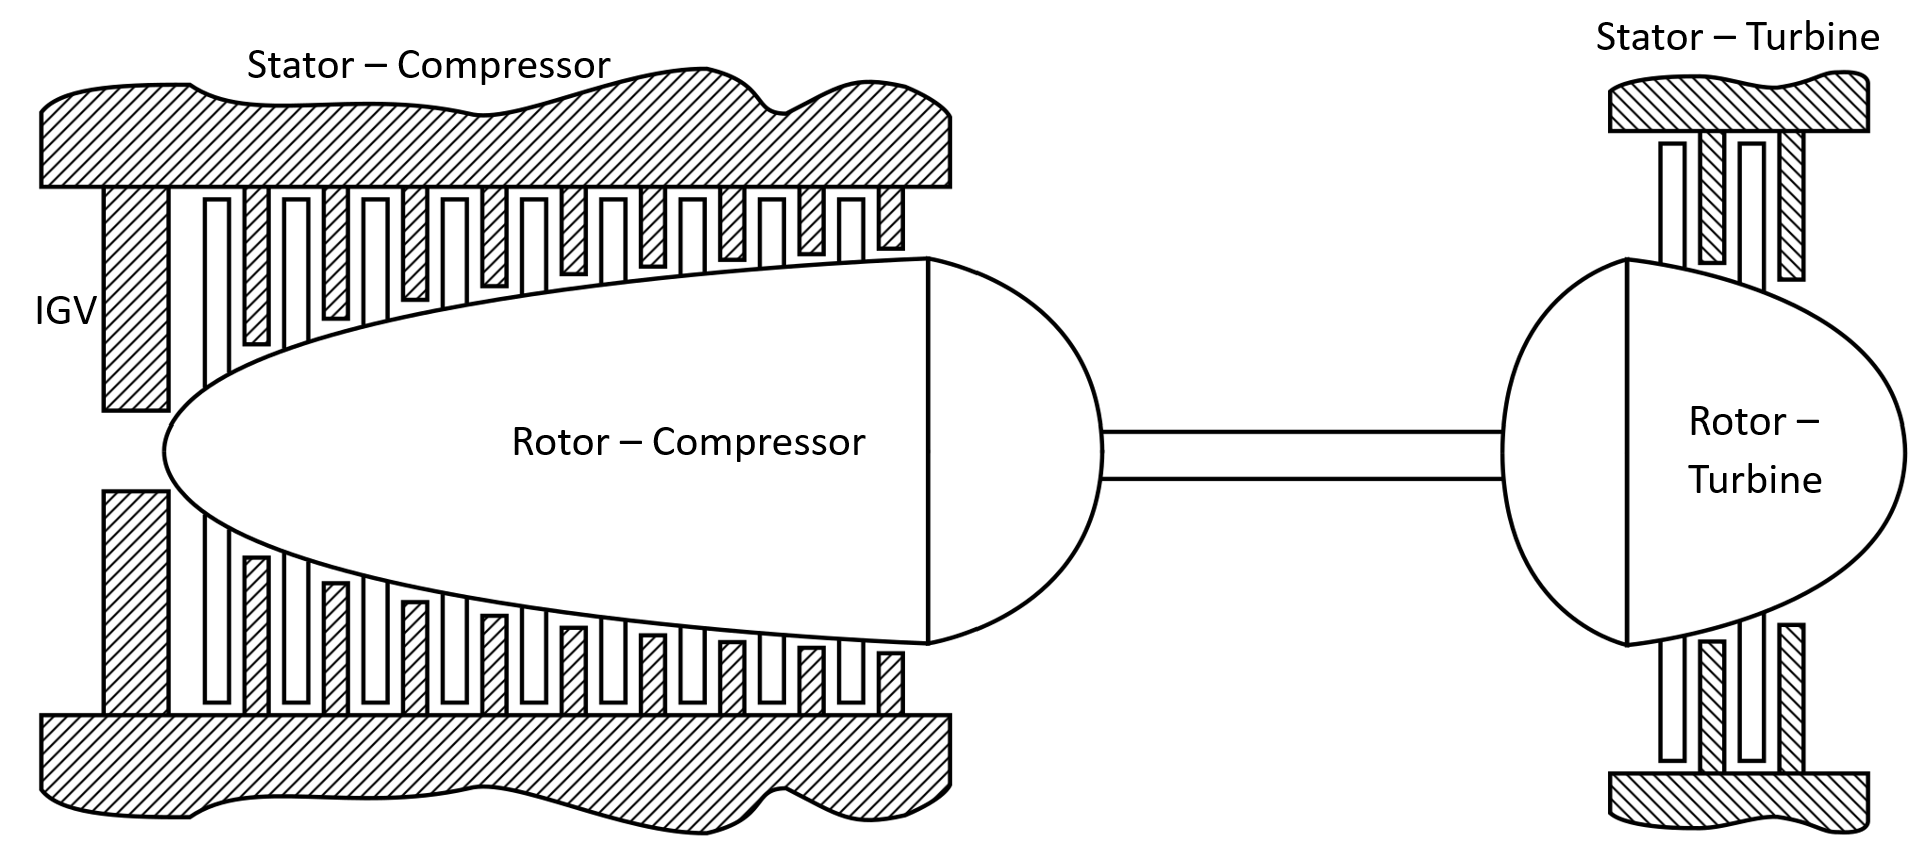

Lets define $T_{\textrm{t4}}$ and $N$ here:

N = 5800;
Tt4 = 1400;

The Blade element theory requires us to define few geometric parameters to predict the compressor and turbine maps for any turbomachinery setup. Let's get that done!

%% Compressor Geometry
geom.comp.ns = 9;                                   % Number of compressor stages
geom.comp.rt = 0.75;                                % Stage 1 tip radius (m)
geom.comp.rh = 0.47;                                % Stage 1 hub radius (m)
geom.comp.alpha2 = 80;                              % Angle alpha_2 (degrees) according to Sforza Fig. 7.41

%% Turbine Geometry
geom.turb.ns = 2;                                   % Number of compressor stages
geom.turb.rt = 0.8;                                 % Stage 1 tip radius (m)
geom.turb.rh = 0.76;                                % Stage 1 hub radius (m)
geom.turb.alpha4 = 90;                              % Angle alpha_2 (degrees) according to Sforza Fig. 7.41

Extra information for turbomachinery enthusiasts: We need some more parameters to solve Blade Element Theory like blade stacking angle, airfoil chord length and blade solidity, however, they are intrinsically defined in the code and you need not worry about them!

Now that we have all the parameters we need, let's see what our compressor map looks like. Note that this is a computation heavy program, and it will try to use parallel cores available on your computer. It typically takes a little while to start the parallel computing process at first, but then it will work much faster later. Depending on your computer's ability you might have to wait for it to generate the compressor maps.

Run the following section to find out what your compressor map looks like! Make sure to pass variable name you are using in place of Tt2 and Pt2.

% compressorMap(Tt2, Pt2, N, geom)

That looks cool! Now that we have our map we are ready to start matching!

### Determining $\dot{m}$ by matching

As we have learnt in the class, the solution for turbomachinery performance starts with making a guess for air mass flow rate. Making a wise initial guess is very important here, as you will learn in later parts of this project. For now, lets define a variable for initial guess of$\dot{\;m}$ and set its value to 230 kg/s.

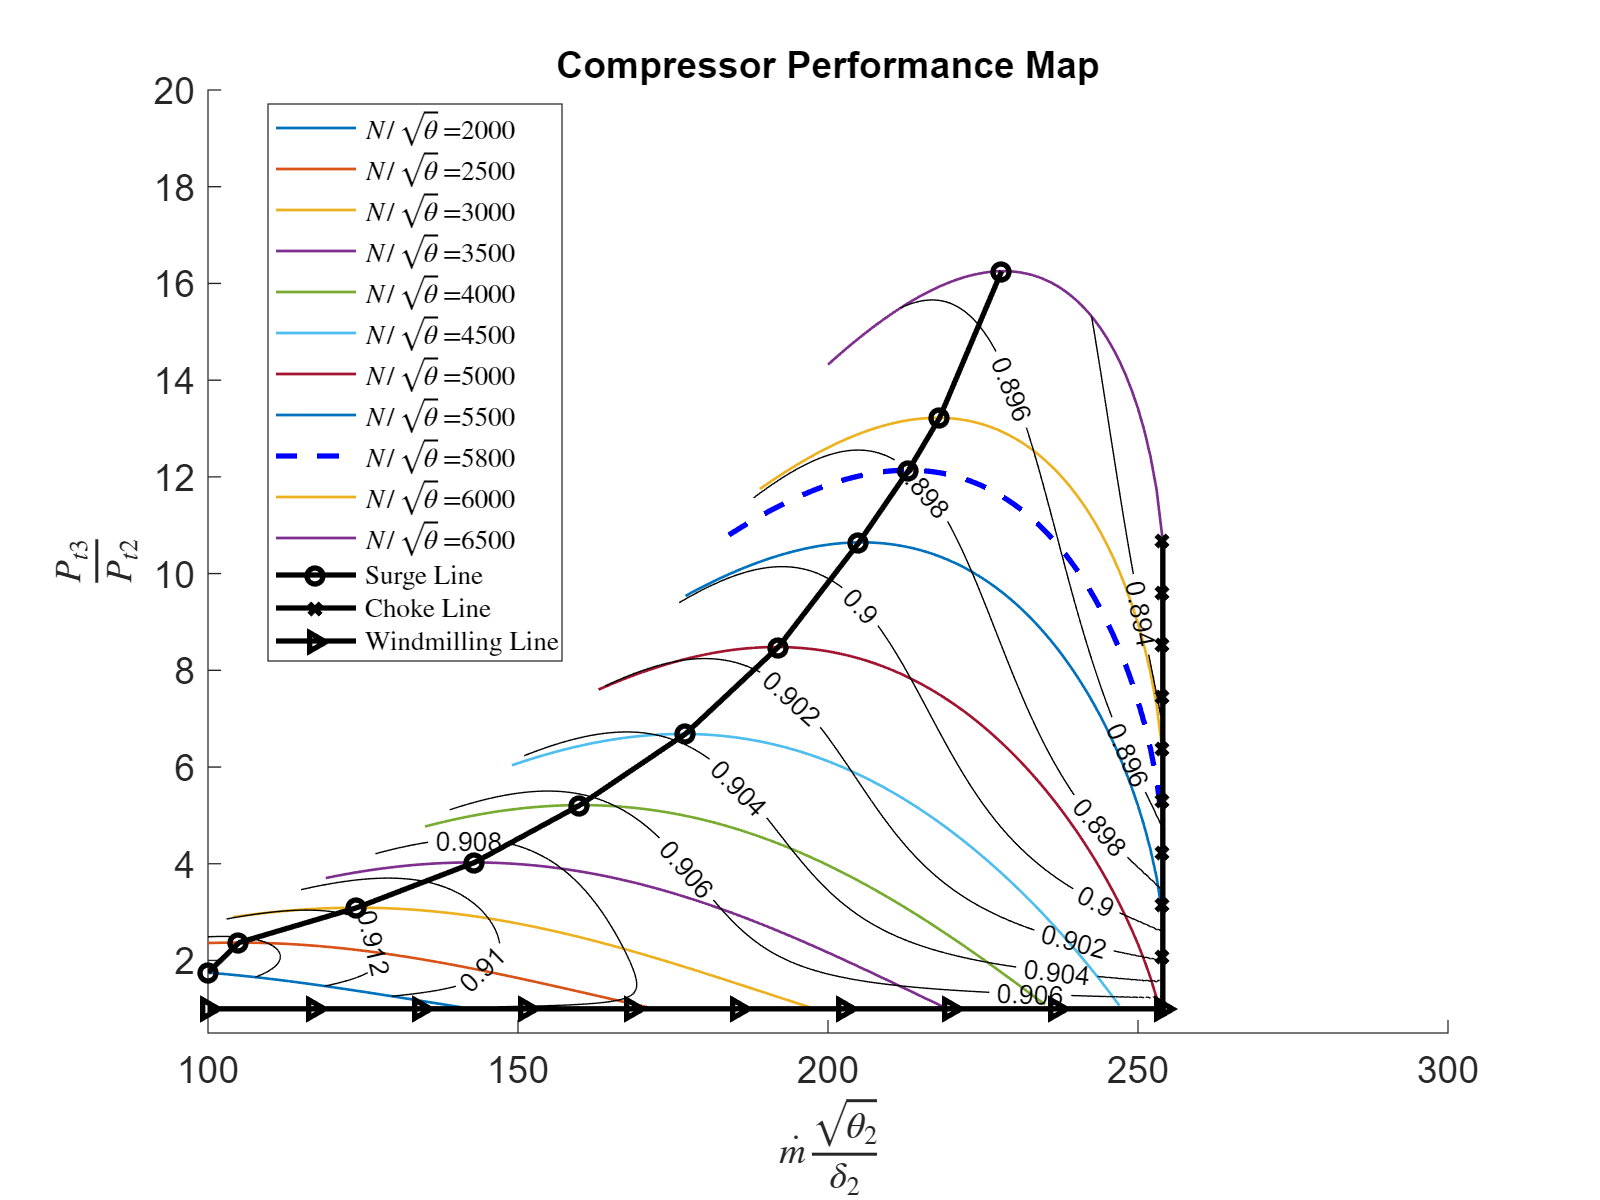

mdot_init = 230;

Next, we will look for$\dot{\;m}$ which leads to ${\dot{W} }_t =|{\dot{W} }_c |$, i.e., matched condition. To do this, you'll need your wfunc.m ready and working, in the same directory as this (seaLevelThrust.mlx) script. The following line runs an in-built function called *fsolve*, which solves set of nonlinear equations.

Let's call the corrected mass flux dataset Mdat.mat here. You will not be using this for your analysis, it is just required to be passed for functioning of the turbomachinery maps.

Mdat = load("Mdat.mat");

Before you run the *fsolve* command make sure you have correct variable names as the input (especially initial guess of $\dot{m}$, it is named *mdot_init *here). Run the following line, and if your wfunc.m is correct, it will give you the mass flow rate which satisfies the matching conditions!

mdot = fsolve(@(x) wfunc(x, N, Tt2, Pt2, Tt4, geom, Mdat), mdot_init)

## Compressor

You can use hub and tip radius to determine the Mach number right at the inlet of compressor, $M_2$. We will have to solve a nonlinear equation for that:


$$\dot{\;m} =\frac{P_t A}{\sqrt{T_t }}\sqrt{\frac{\;\gamma \;}{R}}{M\left(1+\frac{\gamma -1\;}{2}M^2 \right)}^{-\left\lbrack \frac{\gamma +1}{2\left(\gamma -1\right)}\right\rbrack }$$


We will use *anonymous functions *to solve this equation using *fsolve*. Here is an example of how to define a function named *myfun *in terms of variable M. Say we want to determine what $M$results to $P_{\textrm{t2}}$ using the following function:


$$P_{\textrm{t2}} =P_2 {\left(1+\frac{\gamma -1}{2}M^2 \right)}^{\frac{\gamma \;}{\gamma -1}}$$


We would rearrange this equation in the following way:


$$f\left(M\right)=P_{\textrm{t2}} -P_2 {\left(1+\frac{\gamma -1}{2}M^2 \right)}^{\frac{\gamma \;}{\gamma -1}}$$


and solve for$M$such that$f\left(M\right)=0$. Let's define the function$f\left(M\right)$:

*myfunc *will be 0 for$M$which results in this combination of $P_2$ and${\;P}_{\textrm{t2}}$.

Define your function in terms of $M$for mass flow rate for given area here:

A_c = pi*(geom.comp.rt^2 - geom.comp.rh^2);


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


mdot = 221.8790

mdotfun = @(M) mdot - Pt2*A_c/sqrt(Tt2)*sqrt(gamma/R)*M*(1 + (gamma - 1)/2*M^2)^(-(gamma + 1)/(2*(gamma - 1)));

Now, lets use *fsolve *to solve for $M_2$. Run the following line, and before that, don't forget to ensure the variable names match the names you have defined! Here *mdotfun* refers to the function you defined in the previous line of code.

M2 = fsolve(mdotfun, 0.5)

Using $M_2$ you can determine static properties $T_2 ,\;P_2$. Do it in the code block below:

P2 = Pt2/(1 + (gamma - 1)/2*M2^2)^(gamma/(gamma - 1));
T2 = Tt2/(1 + (gamma - 1)/2*M2^2);

Now that we have $\dot{m}$, $N$, $T_{\textrm{t2}}$, and $P_{\textrm{t2}}$, let's use compressor map to determine efficiency and compressor pressure ratio. Since all the maps are in terms of corrected quantities, lets define ${\dot{m} }_{c,2}$ and $N_{c,2\;}$here.

theta2 = Tt2/Tref;


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


M2 = 0.6190

delta2 = Pt2/Pref;
mdotc2 = mdot/delta2*(theta2)^0.5;
Nc2 = N/(theta2)^0.5;

Hold on, we do not need the map, since the computer can give us an exact value! Again, make sure you have the right variable names being passed. Feel free to open *compr.m* to read comments and understand what variables refer to what quantities.

[eta_c, Pr_c, ~, ~, M3, Tt3] = compr(mdotc2, Nc2, Tt2, Pt2, geom, Mdat);

Now that we have all the important quantities, let's find following quantities: $P_3$, $T_3$, $P_{\textrm{t3}}$, and ${\dot{W} }_c$.

Pt3 = Pt2*Pr_c;
T3 = Tt3*(1 + (gamma - 1)/2*M3^2)^-1;
P3 = Pt3*(T3/Tt3)^(gamma/(gamma-1));
Wdot_c = mdot*cp*Tt2/eta_c*(Pr_c^(1 - 1/gamma) - 1);

## Combustor

Let's get to the easiest analysis of this project, combustor! We have already defined $T_{\textrm{t4}}$, but we need $\frac{f}{a}$, $P_{\textrm{t4}}$, $M_4$, $P_4$, and $T_{4\;}$for our result sheet. For the fuel we use, $Q_f =4\ldotp 4\times {10}^7$ KJ/kg. Remember how did you determine $M_2$? You can use the exactly same function with different stagnation properties (*mdotfun*; or whatever you named it).

A_t = pi*(geom.turb.rt^2 - geom.turb.rh^2);
Qf = 4.4e7;
eta_b = 1;
Pt4 = Pt3;
fa = cp*(Tt4 - Tt3)/(Qf*eta_b);                                             % Fuel to Air ratiom fa = cp*(Tt4 - Tt3)/(Qf*eta_b);                                             % Fuel to Air ratio
mdotfun = @(M) mdot - Pt4*A_t/sqrt(Tt4)*sqrt(gamma/R)*M*(1 + (gamma - 1)/2*M^2)^(-(gamma + 1)/(2*(gamma - 1)))
M4 = fsolve(mdotfun, 0.5)

While we are at it, let's determine the corrected quantities for our turbine analysis. Determine ${\dot{m} }_{c,4}$ and $N_{c,4\;}$here.

theta4 = Tt4/Tref;                                                          % Corrected temperature at combustor exit
delta4 = Pt4/Pref;                                                          % Corrected pressure at combustor exit
mdotc4 = mdot/delta4*(theta4)^0.5;
Nc4 = N/(theta4)^0.5;

## Turbine

Want to check out what out turbine maps look like? Run following codes, and be sure to have your variable names corret.

turbineMap(Tt4, Pt4, N, geom)

Now that we have all quantities at the inlet of turbine, let's use* turb.m* to determine turbine exit parameters (again, make sure you got variable names right and don't forget to check out what the variables mean by going to *turb.m*):

[eta_t, Pr_t, ~, ~, M5, Tt5] = turb(mdotc4, Nc4, Tt4, Pt4, geom, Mdat);

mdotfun = function_handle with value:
    @(M)mdot-Pt4*A_t/sqrt(Tt4)*sqrt(gamma/R)*M*(1+(gamma-1)/2*M^2)^(-(gamma+1)/(2*(gamma-1)))


Wow, that was easy! We are ready to determine the turbine exit parameters, $P_5$, $T_5$, $P_{\textrm{t5}}$, and ${\dot{W} }_t$.

Pt5 = Pr_t*Pt4;


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


M4 = 0.6285

T5 = Tt5*(1 + (gamma - 1)/2*M5^2)^-1;
P5 = Pt5*(T5/Tt5)^(gamma/(gamma-1));
Wdot_t = mdot*eta_t*cp*Tt4*(1 - (Pr_t)^(1 - 1/gamma));

## Nozzle

Using the right assumption, let's determine stagnation properties $T_{\textrm{t7}}$, $P_{\textrm{t7}}$:

Pt7 = Pt5;
Tt7 = Tt5;

Well, now that we know how our turbomachinery behaves at sea level, let's design a nozzle which gives us an optimally expanded conditions at sea level, to maximize thrust during take-off. Define $P_7$, $M_7$, $A^*$, $A_7$, $T_7$ and $V_7$.

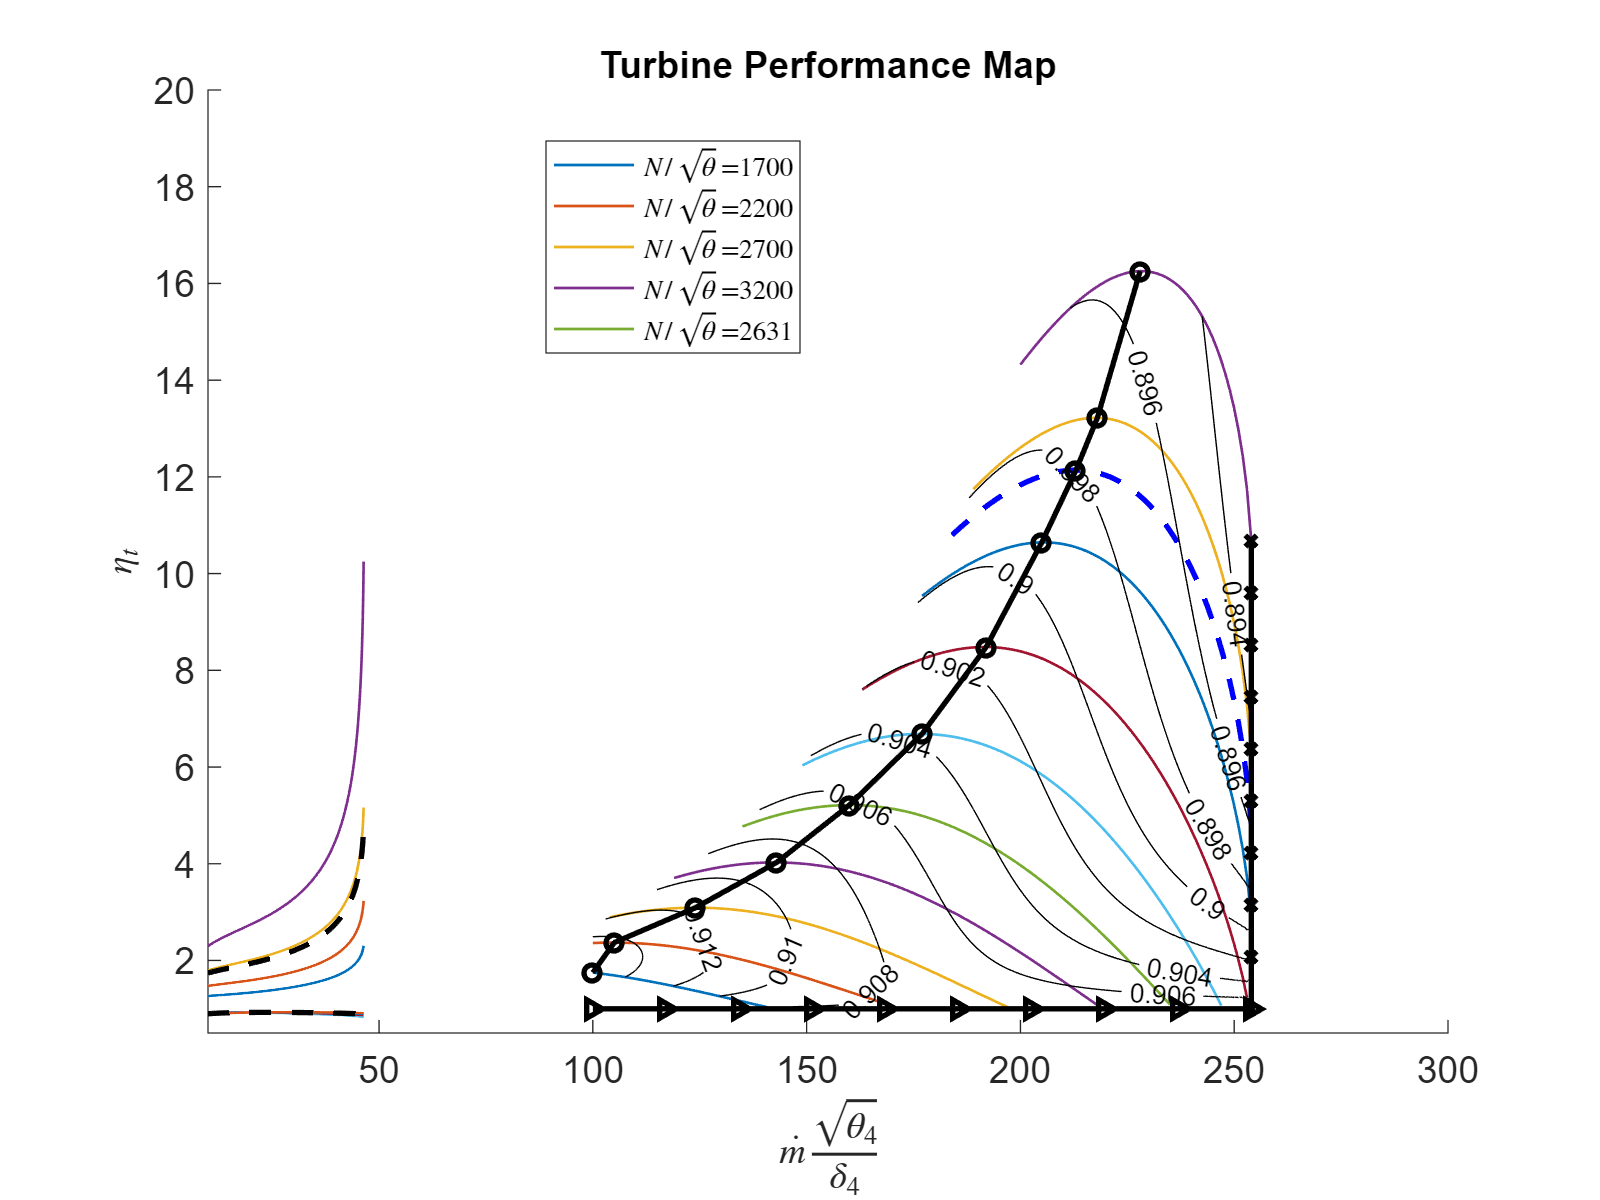

P7 = P0;                                                                    % Correctly expanded

M7 = sqrt((2/(gamma - 1))*((Pt7/P7)^(1 - 1/gamma) - 1));
A_star = mdot/Pt7*sqrt(Tt7)*sqrt(R/gamma)*((gamma + 1)/2)^...
    ((gamma + 1)/(2*(gamma - 1)));
A7 = A_star/M7*((1 + (gamma - 1)/2*M7^2)/((gamma + 1)/2))^((gamma + 1)/(2*(gamma - 1)));
T7 = Tt7/(1 + (gamma - 1)/2*M7^2);
V7 = M7*sqrt(gamma*R*T7);

## Engine Performance Parameters

Wohoo! We made it till the end! We now know how our engine behaves at sea level, so let's gauge its performance. Determine thrust, specific thrust, and specific fuel consumption here:

Thrust = (mdot*(V7 - V0) + A7*(P7 - P0))/1000;
ST = Thrust*1000/mdot;
cj = fa/ST;

Is your engine performing somewhere close to GE4? Do your values make sense? A good sanity check is always advisable.

Congratulations! You have finished characterizing your engine for sea level!

## The End!